# Interpolacion de Lagrange

clear
clc
syms x
equis=[2 3 4]

equis =        2              3              4       


ye=[4 2 8]

ye =        4              2              8       


n=length(equis)

n =        3       


suma=0;
for i=1:n
    pro=1;
    for j=1:n
        if(j~=i)
            pro=pro*(x-equis(j))/(equis(i)-equis(j));
        end
    end
    suma=suma+ye(i)*pro;
end   
modelo=suma

$$modelo = 2\,\left(x-3\right)\,\left(x-4\right)-2\,\left(x-2\right)\,\left(x-4\right)+8\,\left(\frac{x}{2}-1\right)\,\left(x-3\right)$$

modelo=simplify(suma)

$$modelo = 4\,x^{2}-22\,x+32$$

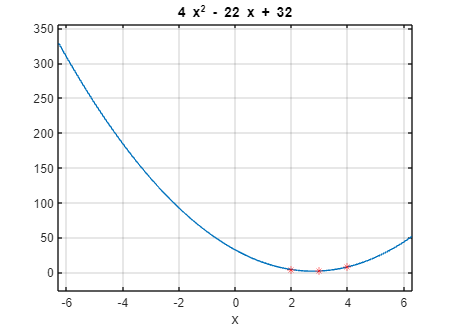

ezplot(modelo)
grid on
hold on
plot(equis,ye,'r*')